# Clearing

clear 
close all
clc


set_param('full_system', "FastRestart", "off");


## Parameters Setting

% Model Parameters

% Posture regulation strategy filename            
% Available options for easy testing:
posture = 'posture_subsys'; 

% Trajectory tracking strategy filename
% Available options for easy testing:
trajectory = 'feed_lin_sagittal_sub';
% trajectory = 'feed_lin_double_deriv_sub';
% trajectory = 'trajectory_tracking_linear_sub';
% trajectory = 'trajectory_tracking_non_linear_sub'; 


distance_threshold = 4;                 % Distance threshold for control strategy switch

% Controller Gains

sagittal_K = [10; 5];                   % Sagittal Axis Controller Gain

double_deriv_Kp = [2 0; 0 5];           % Double Derivative Controller Gains
double_deriv_Kd = [5 0; 0 5];

csi = 1/sqrt(2);                        % (Non)Linear Trajectory Tracking Dampening Factor
a = 5;                                  % " Gain

b = 2;                                  % " Gain


% Test Parameters

N = 150;                                % Number of test runs for validation


% !!! need clarification !!!
delta = 0.01*pi;
results = zeros(N,10);


## Model Control Strategy Setting

% vvv DON'T CHANGE THIS CODE IF YOU DON'T KNOW WHAT YOU ARE DOING !!! vvv

set_param('full_system', "FastRestart", "off");

% Change the posture regulation strategy
set_param('full_system/Agent 1/PR', 'ReferencedSubsystem', posture);

% Change the trajectory tracking strategy
set_param('full_system/Agent 1/TT', 'ReferencedSubsystem', trajectory);

% Save model
 save_system('full_system', 'SaveDirtyReferencedModels', 'on')

% ^^^ --------------------------------------------------------------- ^^^


## Model Validation Through Random Initial Condition Generation

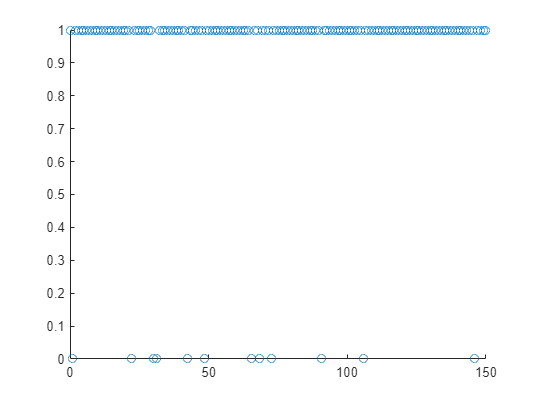

w = warning('off','all');
set_param('full_system', "FastRestart","on");

for i=1:N
    initial_conditions_1 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    initial_conditions_2 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    initial_conditions_3 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    

    initial_conditions_trans_1 = state_transformation([0,0,0], initial_conditions_1);
    initial_conditions_trans_2 = state_transformation([0,0,0], initial_conditions_2);
    initial_conditions_trans_3 = state_transformation([0,0,0], initial_conditions_3);

    out = sim('full_system', "StopTime", "10");
    warning(w);
    check_convergence = out.check.signals.values(end,1);
    
    results(i,:) = [initial_conditions_1 initial_conditions_2 initial_conditions_3 check_convergence];
end

x = linspace(0, N, N);

figure
scatter(x,results(:, 10), "Marker","o")


set_param('full_system', "FastRestart", "off");


## Analytics

successes = sum(results(:, 10));
success_rate = 100 * successes / N

success_rate = 92

## Visualization of a Single Run

%TODO